# Platform path finding using APF

## 2D grid

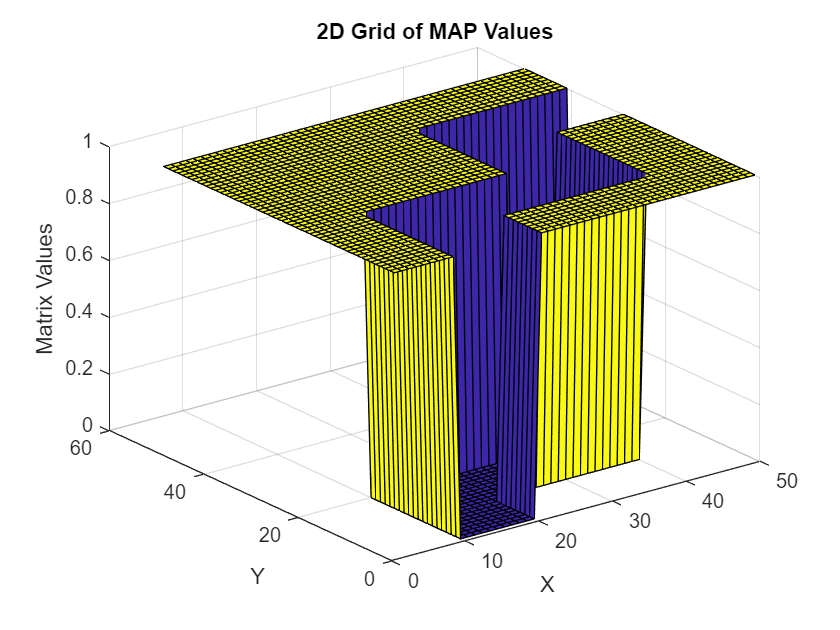

grid = ones(50,50);
grid(10:20,1:20) = 0;
grid(20:40, 10:20) = 0;
grid(30:40, 20:40) = 0;
grid(40:50, 30:40) = 0;

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, grid)
xlabel('X')
ylabel('Y')
zlabel('Matrix Values')
title('2D Grid of MAP Values')

% colorbar

## Repulsive APF - Convolution

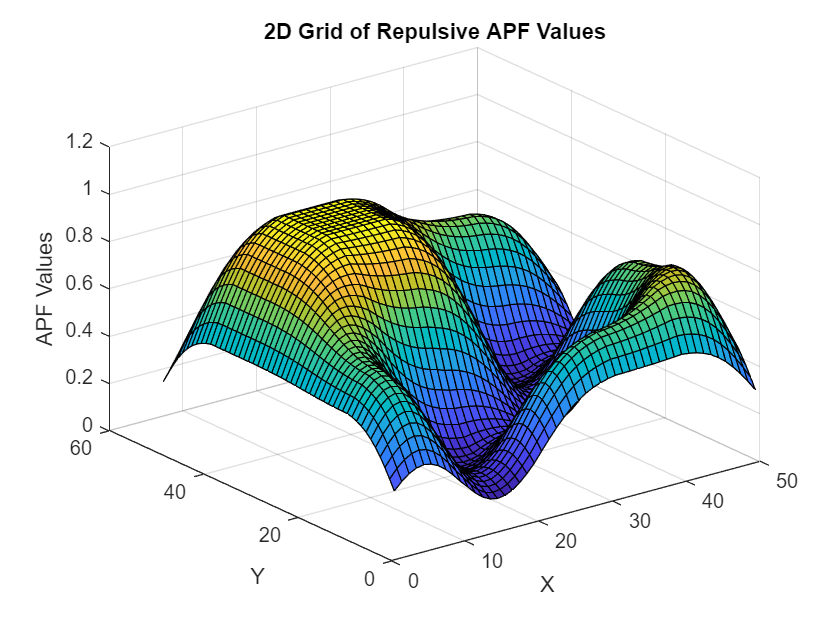

% Set the standard deviation for the Gaussian filter
sigma = 5;

% Define the size of the filter
filterSize = 2 * ceil(2*sigma) + 1;

% Create a grid
[X, Y] = meshgrid(-(filterSize-1)/2 : (filterSize-1)/2);

% Create the Gaussian filter
gaussFilter = exp(-(X.^2 + Y.^2) / (2*sigma^2));
gaussFilter = gaussFilter / sum(gaussFilter(:));  % Normalize the filter

% Convolve the input matrix with the Gaussian filter
repulsive_field = conv2(grid, gaussFilter, 'same');


% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, repulsive_field)
xlabel('X')
ylabel('Y')
zlabel('APF Values')
title('2D Grid of Repulsive APF Values')

## Attractive APF

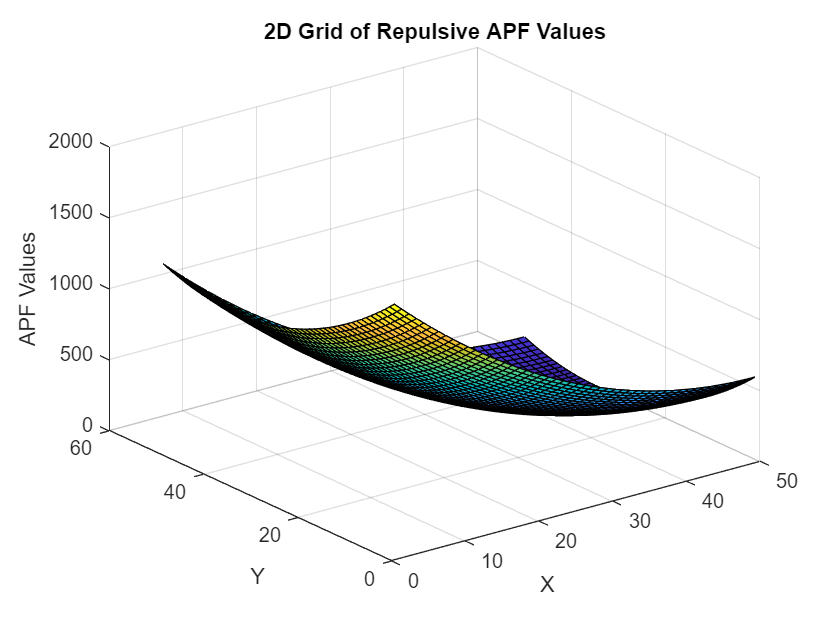

% a 1x2 vector that represents the goal cell (row, column).
goal = [50,35];

% Initialize the matrix to store the attractive potential field.
attractive_field = zeros(size(grid));

% Iterate through every cell in the 2D matrix.
for row = 1:size(grid,1)
    for col = 1:size(grid,2)
        % Calculate the Euclidean distance from each cell to the goal.
        distance = sqrt((row-goal(1))^2 + (col-goal(2))^2);

        % Calculate the attractive potential field for the current cell.
        attractive_field(row, col) = 0.5 * distance^2;
    end
end

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, attractive_field)
xlabel('X')
ylabel('Y')
zlabel('APF Values')
title('2D Grid of Repulsive APF Values')

## Attractive + Repulsive APF

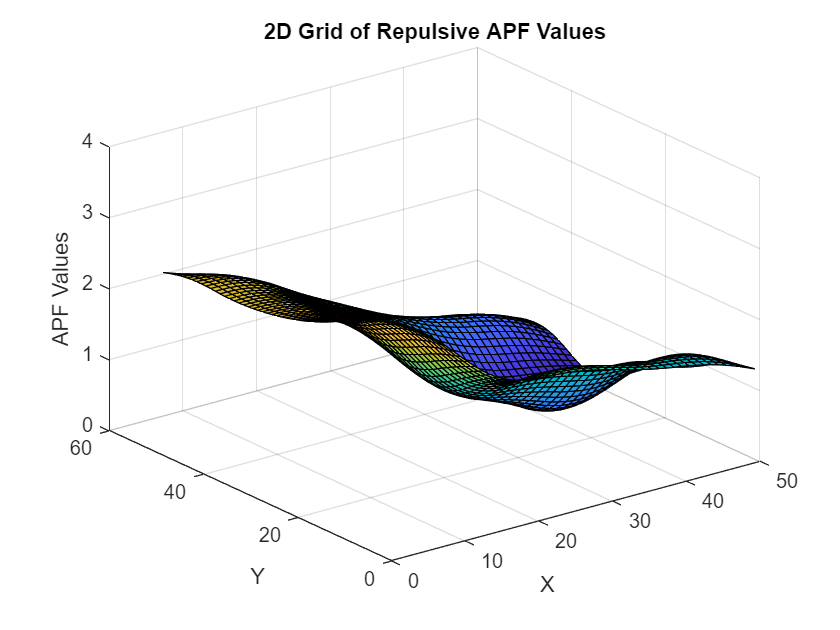

sum_field = attractive_field/max(attractive_field(:))*3 + repulsive_field;

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
figure
surf(Y, X, sum_field)
xlabel('X')
ylabel('Y')
zlabel('APF Values')
title('2D Grid of Repulsive APF Values')

## Path

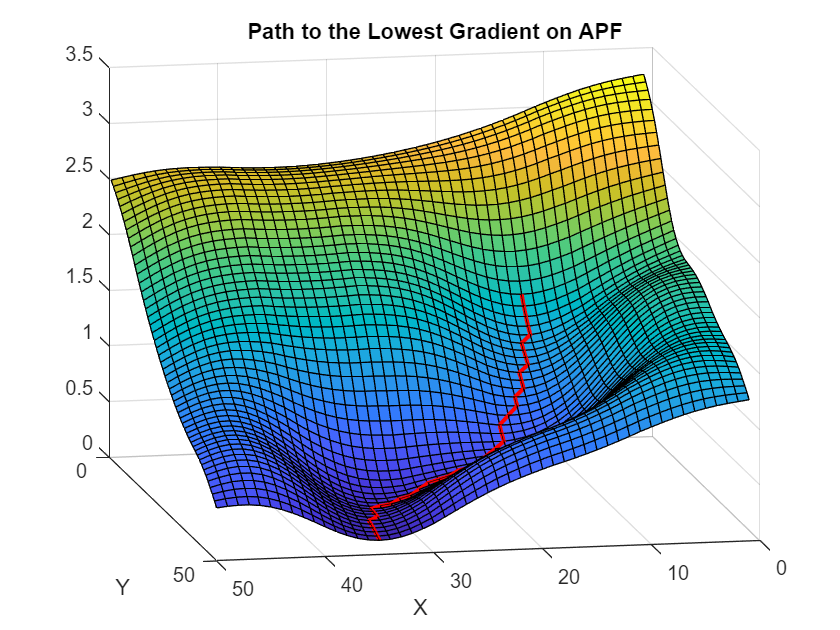

startPoint = [15,15];
path = [];
currentPoint = startPoint;
path = [currentPoint];
currentPrice = sum_field(currentPoint(1), currentPoint(2));
nextPointPrice = currentPrice-0.001;


while (nextPointPrice < currentPrice) * (currentPoint(1)>0) * (currentPoint(1)<50) * (currentPoint(2)>0) * (currentPoint(2)<50)

    % Get local patch of the grid
    localMap = sum_field(currentPoint(1)-1:currentPoint(1)+1, currentPoint(2)-1:currentPoint(2)+1);

    % Find the minimum value and its indices
    [minValue, minRow] = min(localMap(:));
    [minRow, minCol] = ind2sub(size(localMap), minRow);

    % Move to the next point
    currentPoint = [currentPoint(1)+minRow-2, currentPoint(2)+minCol-2];

    % Save next point to path
    path = [path ; currentPoint];

    % Change current price
    currentPrice = nextPointPrice;

    % Get nextPointPrice
    nextPointPrice = sum_field(currentPoint(1), currentPoint(2));


end
% Plot the attractive potential field as a surface
surf(sum_field)
hold on

% Plot the path on top of the surface
plot3(path(:, 2), path(:, 1), sum_field(sub2ind(size(sum_field), path(:, 1), path(:, 2))), 'r', 'LineWidth', 2)

% Add path points on the surface figure
% scatter3(path(:, 2), path(:, 1), ones(size(path, 1)), 'filled', 'r')

% Adjust the view angle
view(140, 40)

% Set the labels and the title
xlabel('X')
ylabel('Y')
title('Path to the Lowest Gradient on APF')